# Trajectories using Puma 560

Invoque the puma object

mdl_puma560

Consider the end-effector of the Puma 560 moving between two  cartesian poses, which describe points in the xy-plane with different end-effector orientations.

T1 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T2 = SE3(0.4, -0.2, 0) * SE3.Rx(pi/2);

The joint coordinate vectors associated with these poses are:

q1 = p560.ikine6s( T1);
q2 = p560.ikine6s(T2);

We require the motion to occur over a time period of 2 seconds in 50 ms time steps

t = [0:0.05:2]';

A joint-space trajectory is formed by smoothly interpolating between the joint configurations q1 and q2. Previously we used the functions 'tpoly' or 'lspb' f in conjunction with the multi-axis driver function 'mtraj'.

All of them results in a 50 × 6 matrix q with one row per time step and one column per joint

q = mtraj(@tpoly, q1, q2, t)

q =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096



q = mtraj(@lspb, q1, q2, t)

q =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2618    2.0791    0.5992   -0.0033    0.4644    0.1231
    3.2579    2.0791    0.5992   -0.0131    0.4677    0.1278
    3.2513    2.0791    0.5992   -0.0294    0.4732    0.1356
    3.2422    2.0791    0.5992   -0.0522    0.4808    0.1466
    3.2305    2.0791    0.5992   -0.0816    0.4907    0.1607
    3.2161    2.0791    0.5992   -0.1175    0.5028    0.1780
    3.1992    2.0791    0.5992   -0.1599    0.5170    0.1984
    3.1796    2.0791    0.5992   -0.2089    0.5334    0.2219
    3.1575    2.0791    0.5992   -0.2644    0.5521    0.2486


Plotting the results: Animation

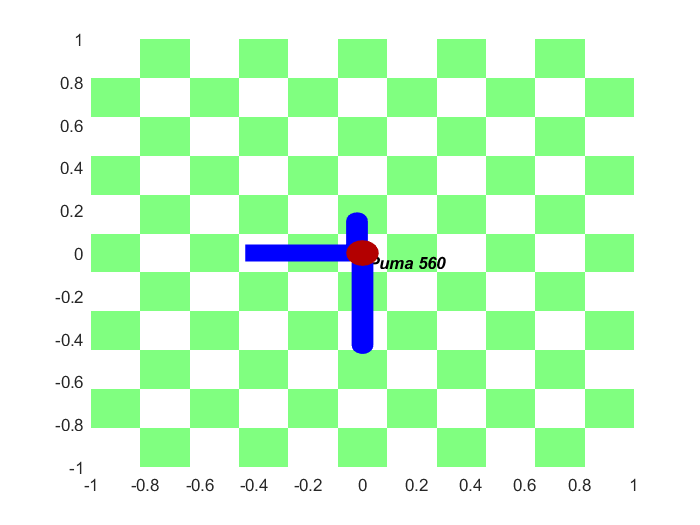

Index exceeds the number of array elements (4).

Error in SerialLink/plot>create_robot (line 469)
            d = norm( d(4:6)-d(1:3) ) / 72;

Error in SerialLink/plot (line 252)
        handle = create_robot(robot, opt);

p560.plot(q)

## Optimized Join trajectory 'jtraj'

This is equivalent to 'mtraj' with 'tpoly' interpolation but optimized for the multi-axis case and also allowing initial and final velocity to be set using additional  arguments.

You can invoque it using both: joint space interpolation or the frame description

q = jtraj(q1, q2, t);

[q,qd,qdd] = jtraj(q1, q2, t);

q = p560.jtraj(T1, T2, t)

q =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096


Plotting the results: understanding the movements

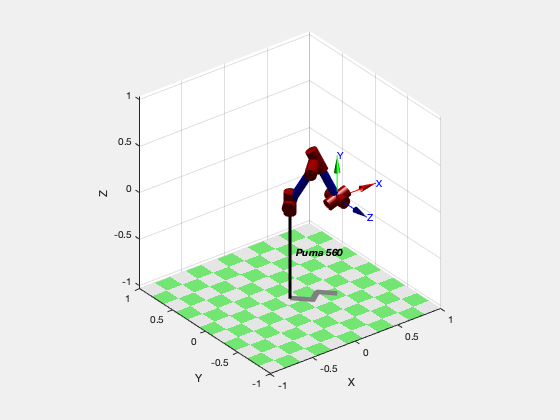

p560.plot(q) % same animation as before

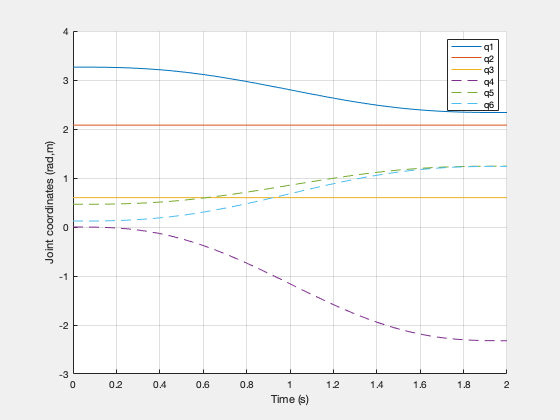

clf % clear the current figure window
qplot(t, q);

clf
T = p560.fkine(q);

p = T.transl;

about(p)

p [double] : 41x3 (984 bytes)


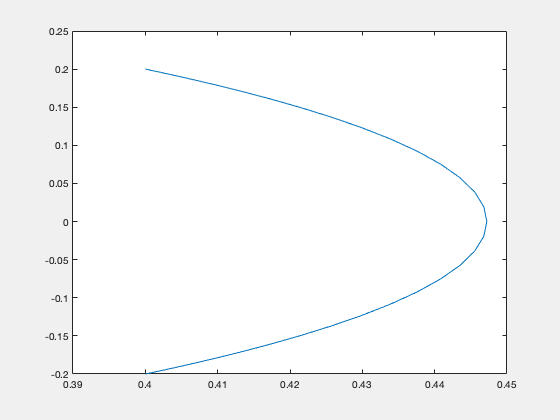


plot(p(:,1), p(:,2))

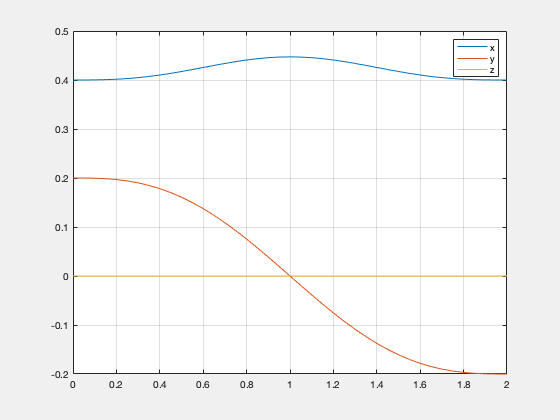


plot(t,p)
grid on
legend('x','y','z')

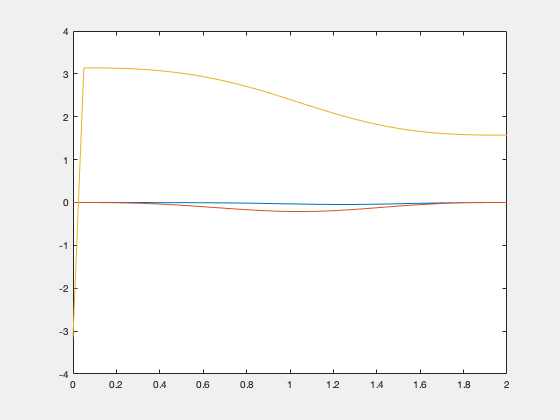


plot(t, T.torpy('xyz'))

## 7.3.2  Cartesian motion

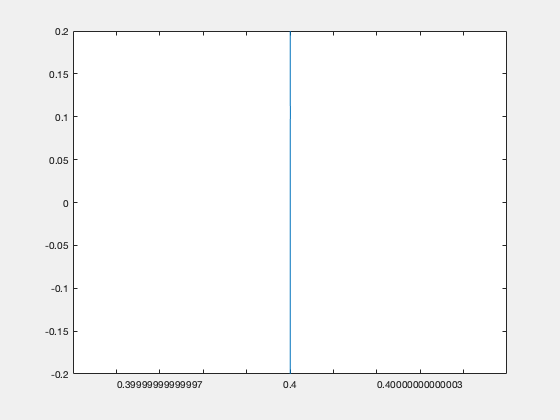

Ts = ctraj(T1, T2, length(t));
p = Ts.transl;

plot(p(:,1), p(:,2))


plot(t, p);
grid on
legend('x','y','z')




p560.plot(p560.ikine6s(T1))
rpy1=T1.torpy('xyz')

rpy1 =          0         0   -3.1416


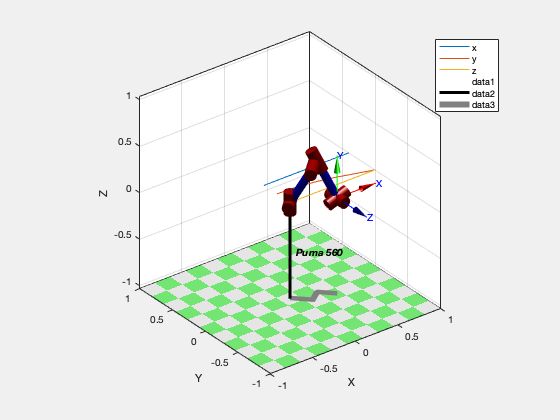


p560.plot(p560.ikine6s(T2))

rpy2=T2.torpy('xyz')

rpy2 =          0         0    1.5708


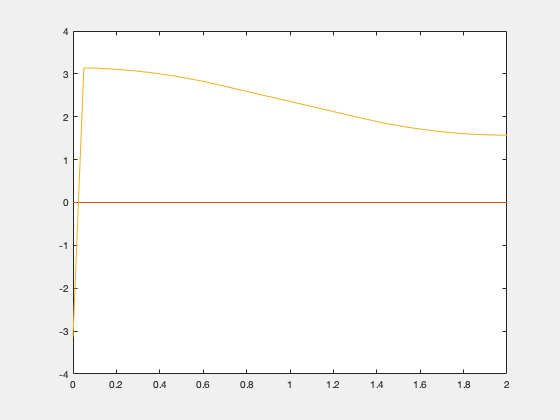

plot(t, Ts.torpy('xyz'));

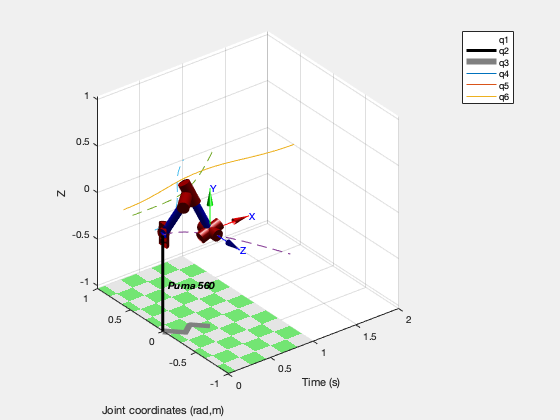


qc = p560.ikine6s(Ts);
clf
p560.plot(qc)

qplot(t,qc)

## 7.3.4  Motion through a singularity

T1 = SE3(0.5, 0.3, 0.44) * SE3.Ry(pi/2);
T2 = SE3(0.5, -0.3, 0.44) * SE3.Ry(pi/2);

Ts = ctraj(T1, T2, length(t));

qc = p560.ikine6s(Ts)

qc =     3.4218    1.8818   -0.3310   -1.5015    0.2808   -1.6429
    3.4203    1.8807   -0.3295   -1.5023    0.2794   -1.6420
    3.4160    1.8774   -0.3252   -1.5048    0.2750   -1.6394
    3.4087    1.8719   -0.3181   -1.5089    0.2677   -1.6350
    3.3985    1.8643   -0.3083   -1.5147    0.2573   -1.6288
    3.3852    1.8548   -0.2960   -1.5224    0.2439   -1.6207
    3.3688    1.8435   -0.2816   -1.5322    0.2274   -1.6104
    3.3492    1.8305   -0.2652   -1.5446    0.2077   -1.5976
    3.3262    1.8162   -0.2473   -1.5604    0.1846   -1.5813
    3.2997    1.8007   -0.2282   -1.5815    0.1581   -1.5599



plot(p(:,1), p(:,2))


plot(t, p);
grid on
legend('x','y','z')

p560.plot(p560.ikine6s(T1))
rpy1=T1.torpy('xyz')

rpy1 =          0    1.5708         0


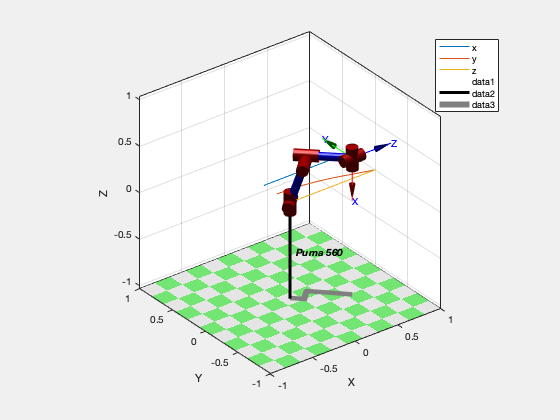


p560.plot(p560.ikine6s(T2))

rpy2=T2.torpy('xyz')

rpy2 =          0    1.5708         0


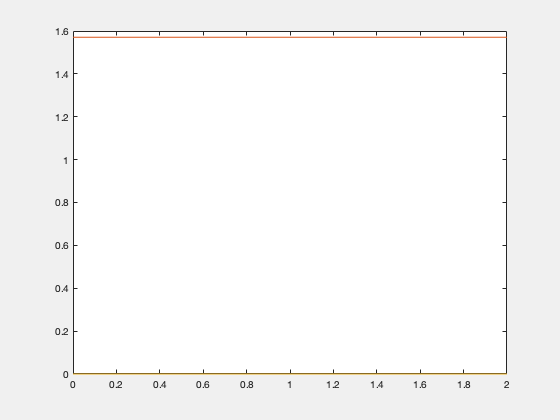


plot(t, Ts.torpy('xyz'));


qc = p560.ikine6s(Ts);
clf
p560.plot(qc)

qplot(t,qc)

Manipulability / dexterity of a manipulator, its ability to move easily in any direction. It is a scalar measure, high is good. 

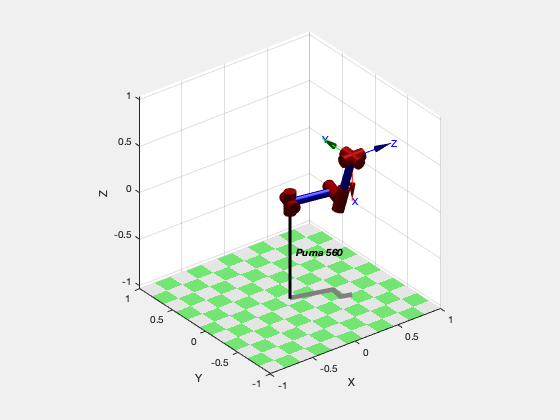

m_ikine6s = p560.maniplty(qc);

plot(t,m)% Notice at some moment m is very slow

qc = p560.ikine(Ts);
m_ikine = p560.maniplty(qc);
clf
p560.plot(qc)

clf
qplot(t,qc)

plot(t,m_ikine)
hold on
plot(t,m_ikine6s)
grid on

## 7.3.5  Configuration change

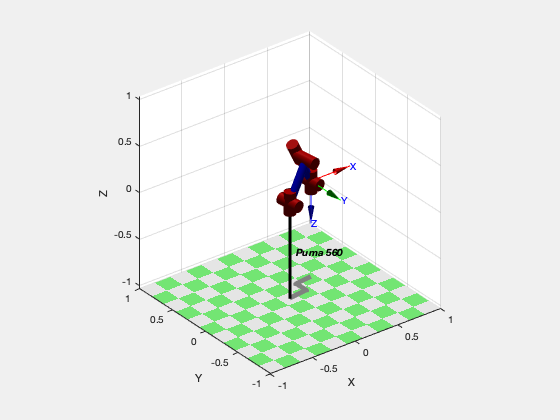

T = SE3(0.4, 0.2, 0) * SE3.Rx(pi);

qr = p560.ikine6s(T, 'ru');
ql = p560.ikine6s(T, 'lu');

q = jtraj(qr, ql, t);
clf
p560.plot(q)